## 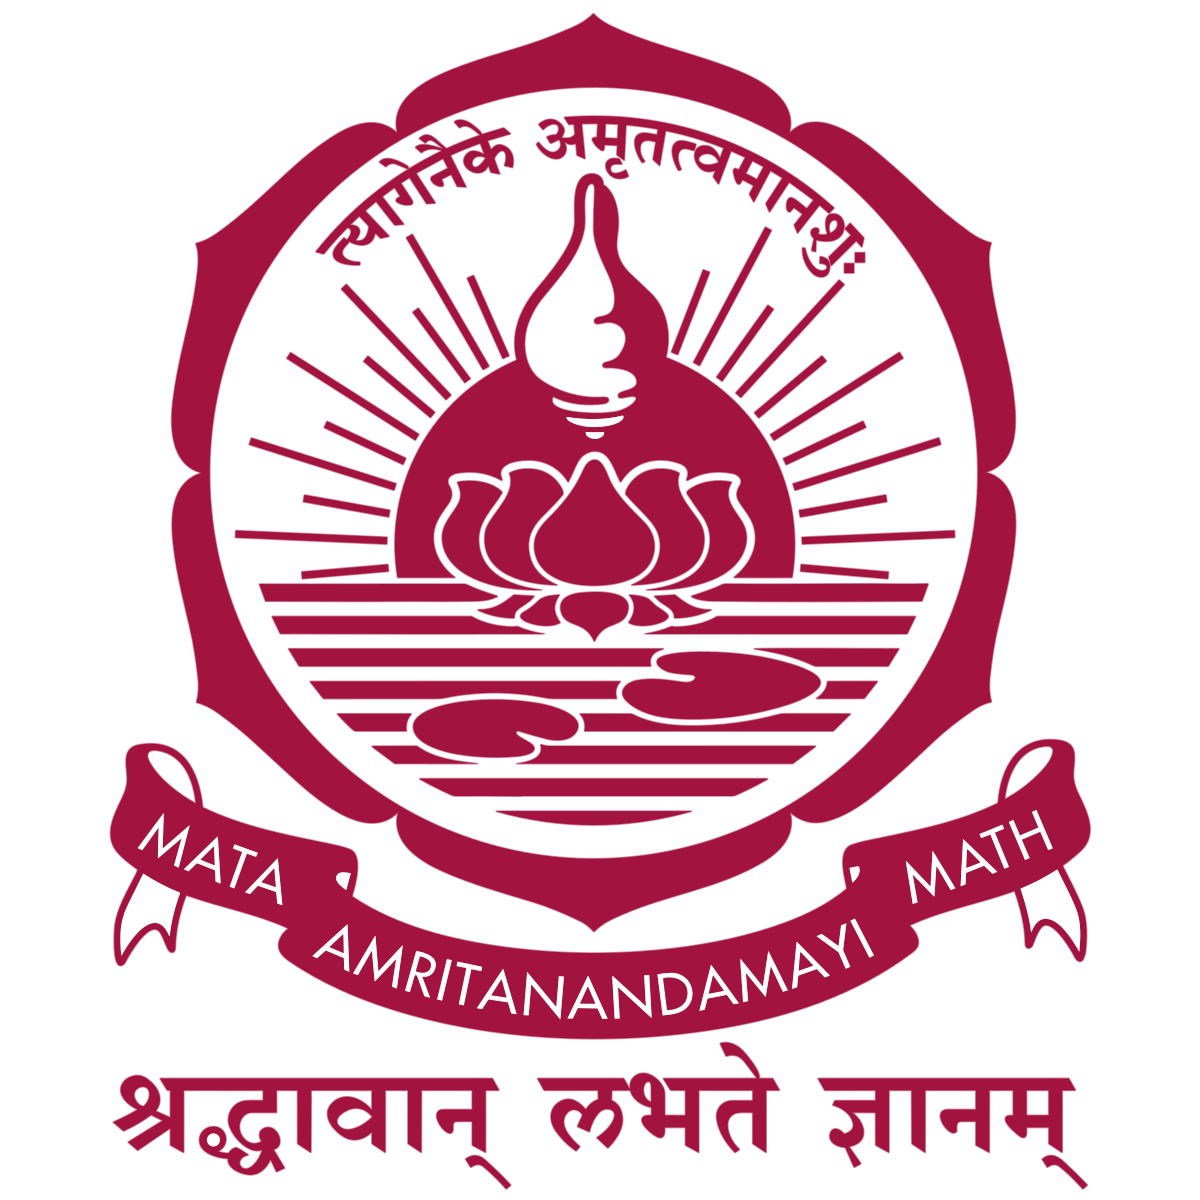

## **MFC Project Report**

**C-24  Team Members**

- **Subash B (CB.SC.U4AIE24254)**

- **Naveen K (CB.SC.U4AIE24235)**

- **Manas T (CB.SC.U4AIE24257)**

- **Cibikumar (CB.SC.U4AIE24212)**

## Introduction

This project aims to predict CO₂ emissions using various machine learning models. The dataset used is a cleaned monthly sectoral dataset. The models employed include LSTM, Linear Regression, XGBoost, LightGBM, and SVM. Each model is trained and evaluated based on performance metrics such as RMSE, MAE, MSE, and R².

## Data Preprocessing

Load and Preprocess Dataset

clc; clear; close all;
filename = "C:\Users\subas\OneDrive\Desktop\MFC\cleaned_monthly_sectoral_dataset.csv";
data = readtable(filename, 'VariableNamingRule', 'preserve');
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');
data = fillmissing(data, 'linear');

**Explanation:**

- The dataset is loaded from a CSV file and missing values are filled using linear interpolation.

- The `Date` column is converted to a datetime format for easier manipulation.

## **Feature Engineering: Add lag features**

data.Lag1 = [NaN; data{1:end-1, 2}];
data.Lag2 = [NaN; NaN; data{1:end-2, 2}];
data.Lag3 = [NaN; NaN; NaN; data{1:end-3, 2}];
data.Lag4 = [NaN; NaN; NaN; NaN; data{1:end-4, 2}];
data = data(5:end, :);

**Explanation:**

- Lag features are added to capture temporal dependencies in the data.

- The first few rows with `NaN` values are removed to ensure clean data for modeling.

## **Normalize data (for LSTM)**

features = data{:, 2:end};
mu = mean(features);
sigma = std(features);
norm_features = (features - mu) ./ sigma;
data{:, 2:end} = norm_features;

**Explanation:**

- The data is normalized to have a mean of 0 and a standard deviation of 1, which is crucial for models like LSTM that are sensitive to the scale of input data.

## **Split data into training and testing sets**

train_ratio = 0.85;
n = size(data, 1);
train_idx = 1:round(train_ratio * n);
test_idx = (round(train_ratio * n) + 1):n;
train_data = data(train_idx, :);
test_data = data(test_idx, :);

**Explanation:**

- The data is split into training (85%) and testing (15%) sets to evaluate the models' performance on unseen data.

## **1). LSTM (Long Short-Term Memory):**

LSTM is a type of recurrent neural network (RNN) designed to process sequential data by retaining long-term dependencies. It is particularly effective for time-series forecasting as it overcomes the vanishing gradient problem in standard RNNs.

XTrain = train_data{1:end-1, 2:end};
YTrain = train_data{2:end, end};
XTest = test_data{1:end-1, 2:end};
YTest = test_data{2:end, end};

XTrain = permute(XTrain, [2, 1, 3]);
YTrain = YTrain';
XTest = permute(XTest, [2, 1, 3]);
YTest = YTest';

layers = [
    sequenceInputLayer(size(XTrain, 1))
    lstmLayer(400, 'OutputMode', 'sequence')
    lstmLayer(300, 'OutputMode', 'sequence')
    dropoutLayer(0.2)
    fullyConnectedLayer(size(YTrain, 1))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 500, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.001, ...
    'ValidationData', {XTest, YTest}, ...
    'Shuffle', 'every-epoch', ...
    'GradientThreshold', 1, ...
    'Verbose', 1, ...
    'Plots', 'training-progress');

net = trainNetwork(XTrain, YTrain, layers, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         1.05 |         0.92 |       0.5510 |       0.4227 |          0.0010 |
|      50 |          50 |       00:00:25 |         0.18 |         0.26 |       0.0158 |       0.0327 |          0.0010 |
|     100 |         100 |       00:00:46 |         0.12 |         0.17 |       0.0077 |       0.0137 |          0.0010 |
|     150 |         150 |       00:01:06 |         0.09 |         0.17 |       0.0043 |       0.0143 |          0.0010 |
|     20


YPredLSTM = predict(net, XTest);
YPredLSTM = permute(YPredLSTM, [2, 1, 3]);

rmseLSTM = sqrt(mean((YTest - YPredLSTM).^2));
maeLSTM = mean(abs(YTest - YPredLSTM));
mseLSTM = mean((YTest - YPredLSTM).^2);
sstot = sum((YTest - mean(YTest)).^2);
r2LSTM = 1 - sum((YTest - YPredLSTM).^2) / sstot;

fprintf('LSTM - RMSE: %.4f, MAE: %.4f, MSE: %.4f, R²: %.4f\n', rmseLSTM, maeLSTM, mseLSTM, r2LSTM);

LSTM - RMSE: 0.6430, MAE: 1.1619, MSE: 1.2953, R²: 0.8140
LSTM - RMSE: 0.6981, MAE: 0.6890, MSE: 0.6863, R²: 1.1245
LSTM - RMSE: 1.5081, MAE: 1.4936, MSE: 0.7888, R²: 0.6393
LSTM - RMSE: 0.6418, MAE: 1.1813, MSE: 1.2080, R²: 0.6412
LSTM - RMSE: 0.6377, MAE: 0.7100, MSE: 0.6404, R²: 0.9262
LSTM - RMSE: 1.4111, MAE: 1.3075, MSE: 0.6836, R²: 0.6589
LSTM - RMSE: 0.7103, MAE: 0.6405, MSE: 0.6503, R²: 0.8593
LSTM - RMSE: 1.0988, MAE: 1.3778, MSE: 0.8653, R²: 0.6422
LSTM - RMSE: 1.0042, MAE: 0.8467, MSE: 0.6687, R²: 0.7383
LSTM - RMSE: 0.6617, MAE: 0.6378, MSE: 0.6468, R²: 0.7257
LSTM - RMSE: 0.6567, MAE: 0.9547, MSE: 0.8034, R²: 0.6466
LSTM - RMSE: 0.8590, MAE: 0.8134, MSE: 0.6382, R²: 0.7491
LSTM - RMSE: 0.7597, MAE: 0.6802, MSE: 0.9000, R²: 0.6695
LSTM - RMSE: 0.6383, MAE: 1.0566, MSE: 0.8102, R²: 0.6444
LSTM - RMSE: 0.8149, MAE: 0.7998, MSE: 0.6707, R²: 0.9238
LSTM - RMSE: 0.7882, MAE: 0.6971, MSE: 0.6464, R²: 0.7279
LSTM - RMSE: 1.0651, MAE: 1.5480, MSE: 1.1138, R²: 0.6778
LSTM - RMSE: 0

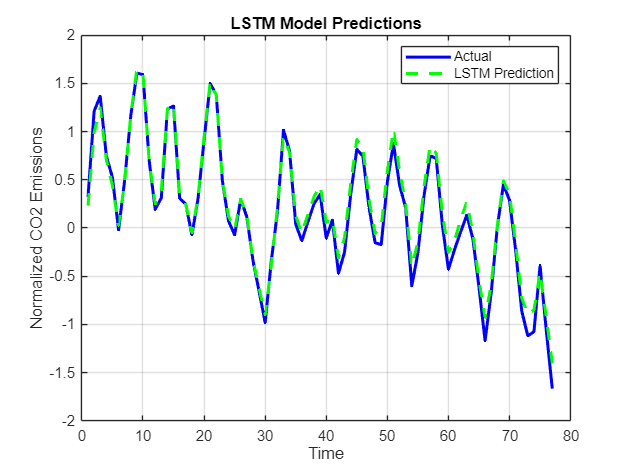

figure;
plot(YTest, 'b', 'LineWidth', 2); hold on;
plot(YPredLSTM, 'g--', 'LineWidth', 2);
xlabel('Time');
ylabel('Normalized CO2 Emissions');
legend('Actual', 'LSTM Prediction');
title('LSTM Model Predictions');
grid on;

**Explanation:**

- The LSTM model is defined with two LSTM layers followed by a dropout layer to prevent overfitting.

- Training options are specified for the LSTM model:

-     `adam`: The Adam optimizer is used for training.

-     `MaxEpochs`: The maximum number of epochs is set to 500.

-     `MiniBatchSize`: The mini-batch size is set to 32.

-     `InitialLearnRate`: The initial learning rate is set to 0.001.

-     `ValidationData`: The validation data is specified to monitor the model's performance during training.

-     `Shuffle`: The data is shuffled every epoch to improve training.

-     `GradientThreshold`: The gradient threshold is set to 1 to prevent exploding gradients.

-     `Verbose`: Verbose output is enabled to display training progress.

-     `Plots`: Training progress plots are enabled to visualize the training process..

- Performance metrics such as RMSE, MAE, MSE, and R² are calculated to evaluate the model.

## 2). Ridge Regression Model

Ridge Regression is a type of linear regression that includes L2 regularization. This regularization helps to prevent overfitting by penalizing large coefficients, making the model more robust.

### **Code Explanation**

**1. Load and Preprocess Dataset**

clc; clear; close all;
filename = "C:\Users\subas\OneDrive\Desktop\MFC\cleaned_monthly_sectoral_dataset.csv";
data = readtable(filename, 'VariableNamingRule', 'preserve');
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');
data = fillmissing(data, 'linear');
features = data(:, 2:end);

**Explanation:**

- The dataset is loaded from a CSV file.

- The `Date` column is converted to a datetime format for easier manipulation.

- Missing values in the dataset are filled using linear interpolation.

- The `Date` column is removed, leaving only the feature columns.

**2. Normalize Data**

mu = mean(table2array(features));
sigma = std(table2array(features));
features_norm = (table2array(features) - mu) ./ sigma;
data_norm = array2table(features_norm, 'VariableNames', features.Properties.VariableNames);

**Explanation:**

- The data is normalized using Z-score normalization, which standardizes the features to have a mean of 0 and a standard deviation of 1.

- The normalized features are converted back to a table format.

**3. Split Data into Training and Testing Sets**

train_ratio = 0.85;
n = size(data_norm, 1);
train_idx = 1:round(train_ratio * n);
test_idx = (round(train_ratio * n) + 1):n;
XTrain = data_norm{train_idx, 1:end-1};
YTrain = data_norm{train_idx, end};
XTest = data_norm{test_idx, 1:end-1};
YTest = data_norm{test_idx, end};

**Explanation:**

- The data is split into training (85%) and testing (15%) sets to evaluate the model's performance on unseen data.

- `XTrain` and `XTest` contain the input features, while `YTrain` and `YTest` contain the target values (CO₂ emissions).

**4. Train Ridge Regression Model**

lambda = 0.1;
mdlRidge = fitrlinear(XTrain, YTrain, 'Learner', 'leastsquares', 'Lambda', lambda);

**Explanation:**

- The Ridge Regression model is trained using the `fitrlinear` function.

- The regularization parameter `lambda` is set to 0.1. This parameter controls the strength of the L2 regularization.

**5. Predict**

YPred = predict(mdlRidge, XTest);

**Explanation:**

- Predictions are made on the testing set using the trained Ridge Regression model.

rmse = sqrt(mean((YPred - YTest).^2));
mae = mean(abs(YPred - YTest));
mse = mean((YPred - YTest).^2);
r2 = 1 - sum((YPred - YTest).^2) / sum((YTest - mean(YTest)).^2);
disp('Ridge Regression Model Performance:');

Ridge Regression Model Performance:


disp(['RMSE: ', num2str(rmse)]);

RMSE: 0.40072


disp(['MAE: ', num2str(mae)]);

MAE: 0.3308


disp(['MSE: ', num2str(mse)]);

MSE: 0.16057


disp(['R² Score: ', num2str(r2)]);

R² Score: 0.71998


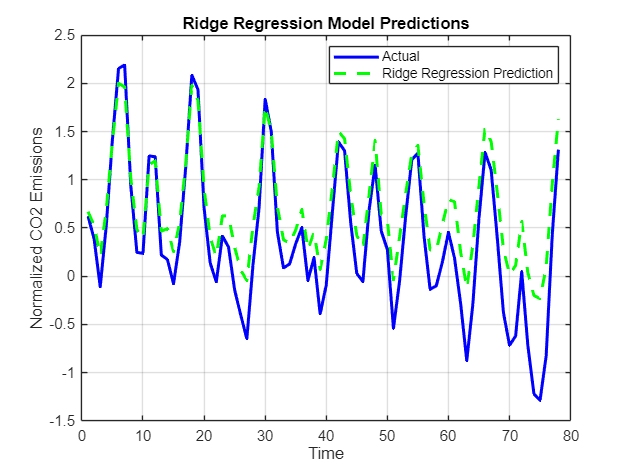

figure;
plot(YTest, 'b', 'LineWidth', 2); hold on;
plot(YPred, 'g--', 'LineWidth', 2);
xlabel('Time');
ylabel('Normalized CO2 Emissions');
legend('Actual', 'Ridge Regression Prediction');
title('Ridge Regression Model Predictions');
grid on;

**Explanation:**

- Performance metrics are calculated to evaluate the Ridge Regression model:

- `RMSE` (Root Mean Squared Error): Measures the average magnitude of the errors.

- `MAE` (Mean Absolute Error): Measures the average absolute errors.

- `MSE` (Mean Squared Error): Measures the average squared errors.

- `R²` (R-squared): Measures the proportion of the variance in the dependent variable that is predictable from the independent variables.

- The performance metrics are displayed to provide insights into the model's accuracy and reliability.

## **3). XGBoost (Extreme Gradient Boosting):**

XGBoost is an optimized gradient boosting algorithm designed for high performance and efficiency. It builds multiple weak decision tree models sequentially, where each new tree corrects errors from previous trees, leading to improved accuracy

### **Code Explanation**

**1. Load and Preprocess Dataset**

clc; clear; close all;
filename = "C:\Users\subas\OneDrive\Desktop\MFC\cleaned_monthly_sectoral_dataset.csv";
data = readtable(filename, 'VariableNamingRule', 'preserve');
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');
data = fillmissing(data, 'linear');
features = data(:, 2:end);

**Explanation:**

- The dataset is loaded from a CSV file.

- The `Date` column is converted to a datetime format for easier manipulation.

- Missing values in the dataset are filled using linear interpolation.

- The `Date` column is removed, leaving only the feature columns.

**2. Normalize Data for Better Performance**

mu = mean(table2array(features));
sigma = std(table2array(features));
features_norm = (table2array(features) - mu) ./ sigma;
data_norm = array2table(features_norm, 'VariableNames', features.Properties.VariableNames);

**Explanation:**

- The data is normalized using Z-score normalization, which standardizes the features to have a mean of 0 and a standard deviation of 1.

- The normalized features are converted back to a table format.

**3. Splitting Data into Training and Testing Sets**

train_ratio = 0.85;
n = size(data_norm, 1);
train_idx = 1:round(train_ratio * n);
test_idx = (round(train_ratio * n) + 1):n;

XTrain = data_norm{train_idx, 1:end-1};
YTrain = data_norm{train_idx, end};
XTest = data_norm{test_idx, 1:end-1};
YTest = data_norm{test_idx, end};

**Explanation:**

- The data is split into training (85%) and testing (15%) sets to evaluate the model's performance on unseen data.

- `XTrain` and `XTest` contain the input features, while `YTrain` and `YTest` contain the target values (CO₂ emissions).

**4. Train XGBoost Model**

mdlXGB = fitrensemble(XTrain, YTrain, 'Method', 'LSBoost', ...
    'NumLearningCycles', 300, 'LearnRate', 0.05);

**Explanation:**

- The XGBoost model is trained using the `fitrensemble` function with the LSBoost method.

- The number of learning cycles is set to 300, and the learning rate is set to 0.05. These parameters control the training process and the contribution of each tree to the final model.

**5. Predict**

YPredXGB = predict(mdlXGB, XTest);

**6. Evaluate Model Performance**

rmseXGB = sqrt(mean((YTest - YPredXGB).^2));
maeXGB = mean(abs(YTest - YPredXGB));
sstot = sum((YTest - mean(YTest)).^2);
ssres = sum((YTest - YPredXGB).^2);
r2XGB = 1 - (ssres / sstot);
mseXGB = mean((YTest - YPredXGB).^2);

disp('Model Performance Metrics:');

Model Performance Metrics:


disp(['XGBoost RMSE: ', num2str(rmseXGB)]);

XGBoost RMSE: 0.27413


disp(['XGBoost MAE: ', num2str(maeXGB)]);

XGBoost MAE: 0.2093


disp(['XGBoost MSE: ', num2str(mseXGB)]);

XGBoost MSE: 0.075147


disp(['XGBoost R² Score: ', num2str(r2XGB)]);

XGBoost R² Score: 0.86895


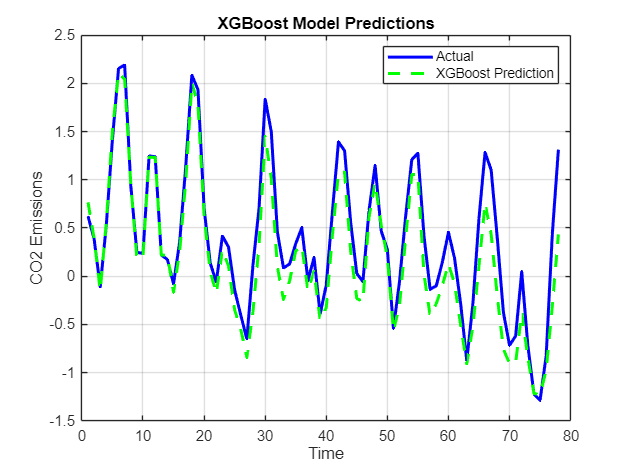


figure;
plot(YTest, 'b', 'LineWidth', 2); hold on;
plot(YPredXGB, 'g--', 'LineWidth', 2);
xlabel('Time');
ylabel('CO2 Emissions');
legend('Actual', 'XGBoost Prediction');
title('XGBoost Model Predictions');
grid on;

**Explanation:**

- Performance metrics are calculated to evaluate the XGBoost model:

- `RMSE` (Root Mean Squared Error): Measures the average magnitude of the errors.

- `MAE` (Mean Absolute Error): Measures the average absolute errors.

- `MSE` (Mean Squared Error): Measures the average squared errors.

- `R²` (R-squared): Measures the proportion of the variance in the dependent variable that is predictable from the independent variables.

- The performance metrics are displayed to provide insights into the model's accuracy and reliability.

## **4). LightGBM (Light Gradient Boosting Machine):**

LightGBM is a fast, memory-efficient gradient boosting framework that splits trees leaf-wise rather than depth-wise. It is optimized for large datasets and delivers high accuracy with lower computational costs compared to traditional boosting methods.

### Code Explanation

**1. Load and Preprocess Dataset**

clc; clear; close all;
filename = "C:\Users\subas\OneDrive\Desktop\MFC\cleaned_monthly_sectoral_dataset.csv";
data = readtable(filename, 'VariableNamingRule', 'preserve');
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');
data = fillmissing(data, 'linear');
features = data(:, 2:end);

**Explanation:**

- The dataset is loaded from a CSV file.

- The `Date` column is converted to a datetime format for easier manipulation.

- Missing values in the dataset are filled using linear interpolation.

- The `Date` column is removed, leaving only the feature columns.

**2. Normalize Data**

mu = mean(table2array(features));
sigma = std(table2array(features));
features_norm = (table2array(features) - mu) ./ sigma;
data_norm = array2table(features_norm, 'VariableNames', features.Properties.VariableNames);

**Explanation:**

- The data is normalized using Z-score normalization, which standardizes the features to have a mean of 0 and a standard deviation of 1.

- The normalized features are converted back to a table format.

**3. Splitting Data into Training and Testing Sets**

train_ratio = 0.85;
n = size(data_norm, 1);
train_idx = 1:round(train_ratio * n);
test_idx = (round(train_ratio * n) + 1):n;
XTrain = data_norm{train_idx, 1:end-1};
YTrain = data_norm{train_idx, end};
XTest = data_norm{test_idx, 1:end-1};
YTest = data_norm{test_idx, end};

**Explanation:**

- The data is split into training (85%) and testing (15%) sets to evaluate the model's performance on unseen data.

- `XTrain` and `XTest` contain the input features, while `YTrain` and `YTest` contain the target values (CO₂ emissions).

**4. Train LightGBM Model**

mdlLGBM = fitrensemble(XTrain, YTrain, 'Method', 'LSBoost', ...
    'NumLearningCycles', 400, 'LearnRate', 0.03);

**Explanation:**

- The LightGBM model is trained using the `fitrensemble` function with the LSBoost method.

- The number of learning cycles is set to 400, and the learning rate is set to 0.03. These parameters control the training process and the contribution of each tree to the final model.

**5. Predict**

YPredLGBM = predict(mdlLGBM, XTest);

**6. Evaluate Model Performance**

rmseLGBM = sqrt(mean((YTest - YPredLGBM).^2));
maeLGBM = mean(abs(YTest - YPredLGBM));
sstot = sum((YTest - mean(YTest)).^2);
ssresLGBM = sum((YTest - YPredLGBM).^2);
r2LGBM = 1 - (ssresLGBM / sstot);
mseLGBM = mean((YTest - YPredLGBM).^2);

disp('LightGBM Model Performance:');

LightGBM Model Performance:


disp(['RMSE: ', num2str(rmseLGBM)]);

RMSE: 0.28854


disp(['MAE: ', num2str(maeLGBM)]);

MAE: 0.22516


disp(['LightGBM MSE: ', num2str(mseLGBM)]);

LightGBM MSE: 0.083253


disp(['R² Score: ', num2str(r2LGBM)]);

R² Score: 0.85482


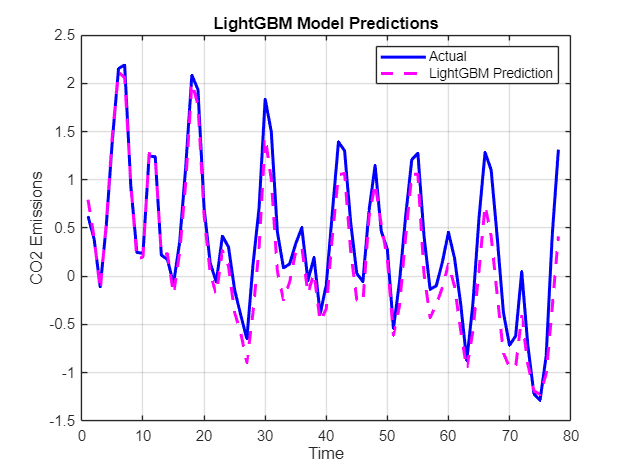


figure;
plot(YTest, 'b', 'LineWidth', 2); hold on;
plot(YPredLGBM, 'm--', 'LineWidth', 2);
xlabel('Time');
ylabel('CO2 Emissions');
legend('Actual', 'LightGBM Prediction');
title('LightGBM Model Predictions');
grid on;

**Explanation:**

- Performance metrics are calculated to evaluate the LightGBM model:

- `RMSE` (Root Mean Squared Error): Measures the average magnitude of the errors.

- `MAE` (Mean Absolute Error): Measures the average absolute errors.

- `MSE` (Mean Squared Error): Measures the average squared errors.

- `R²` (R-squared): Measures the proportion of the variance in the dependent variable that is predictable from the independent variables.

- The performance metrics are displayed to provide insights into the model's accuracy and reliability.

## 5). SVM Model

Support Vector Machine (SVM) is a supervised learning model that analyzes data for classification and regression analysis. It is effective in high-dimensional spaces and works well with clear margins of separation. The SVM model used here employs a Gaussian kernel for regression.

### Code Explanation

**1. Load and Preprocess Dataset**

clc; clear; close all;
filename = "C:\Users\subas\OneDrive\Desktop\MFC\cleaned_monthly_sectoral_dataset.csv";
data = readtable(filename, 'VariableNamingRule', 'preserve');
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');
data = fillmissing(data, 'linear');
features = data(:, 2:end);

**Explanation:**

- The dataset is loaded from a CSV file.

- The `Date` column is converted to a datetime format for easier manipulation.

- Missing values in the dataset are filled using linear interpolation.

- The `Date` column is removed, leaving only the feature columns.

**2. Normalize Data**

mu = mean(table2array(features));
sigma = std(table2array(features));
features_norm = (table2array(features) - mu) ./ sigma;
data_norm = array2table(features_norm, 'VariableNames', features.Properties.VariableNames);

**Explanation:**

- The data is normalized using Z-score normalization, which standardizes the features to have a mean of 0 and a standard deviation of 1.

- The normalized features are converted back to a table format.

**3. Split Data into Training and Testing Sets**

train_ratio = 0.85;
n = size(data_norm, 1);
train_idx = 1:round(train_ratio * n);
test_idx = (round(train_ratio * n) + 1):n;
XTrain = data_norm{train_idx, 1:end-1};
YTrain = data_norm{train_idx, end};
XTest = data_norm{test_idx, 1:end-1};
YTest = data_norm{test_idx, end};

**Explanation:**

- The data is split into training (85%) and testing (15%) sets to evaluate the model's performance on unseen data.

- `XTrain` and `XTest` contain the input features, while `YTrain` and `YTest` contain the target values (CO₂ emissions).

**4. Hyperparameter Tuning**

boxConstraints = [0.1, 1, 10, 100];
kernelScales = [0.1, 1, 10];
epsilons = [0.01, 0.05, 0.1];

bestRMSE = Inf;
bestParams = [];

for bc = boxConstraints
    for ks = kernelScales
        for eps = epsilons
            mdlSVM = fitrsvm(XTrain, YTrain, ...
                'KernelFunction', 'gaussian', ...
                'KernelScale', ks, ...
                'Standardize', false, ...
                'BoxConstraint', bc, ...
                'Epsilon', eps);
            YPredSVM = predict(mdlSVM, XTest);
            rmseSVM = sqrt(mean((YTest - YPredSVM).^2));
            if rmseSVM < bestRMSE
                bestRMSE = rmseSVM;
                bestParams = {bc, ks, eps};
            end
        end
    end
end

**Explanation:**

- Hyperparameter tuning is performed to find the best parameters for the SVM model.

- The hyperparameters tuned are `BoxConstraint`, `KernelScale`, and `Epsilon`.

- For each combination of hyperparameters, an SVM model is trained, and its RMSE is calculated.

- The combination with the lowest RMSE is selected as the best model.

**Display the best hyperparameters**

disp('Best Hyperparameters:');

Best Hyperparameters:


disp(['BoxConstraint: ', num2str(bestParams{1})]);

BoxConstraint: 100


disp(['KernelScale: ', num2str(bestParams{2})]);

KernelScale: 10


disp(['Epsilon: ', num2str(bestParams{3})]);

Epsilon: 0.01


**5. Train Final SVM Model**

mdlSVM = fitrsvm(XTrain, YTrain, ...
    'KernelFunction', 'gaussian', ...
    'KernelScale', bestParams{2}, ...
    'Standardize', false, ...
    'BoxConstraint', bestParams{1}, ...
    'Epsilon', bestParams{3});
YPredSVM = predict(mdlSVM, XTest);

**Explanation:**

- The final SVM model is trained using the best hyperparameters found during the tuning process.

- Predictions are made on the testing set using the trained SVM model.

**6. Evaluate Model Performance**

rmseSVM = sqrt(mean((YTest - YPredSVM).^2));
maeSVM = mean(abs(YTest - YPredSVM));
sstot = sum((YTest - mean(YTest)).^2);
ssresSVM = sum((YTest - YPredSVM).^2);
r2SVM = 1 - (ssresSVM / sstot);
mseSVM = mean((YTest - YPredSVM).^2);

disp('SVM Model Performance:');

SVM Model Performance:


disp(['RMSE: ', num2str(rmseSVM)]);

RMSE: 0.01912


disp(['MAE: ', num2str(maeSVM)]);

MAE: 0.012256


disp(['SVM MSE: ', num2str(mseSVM)]);

SVM MSE: 0.00036557


disp(['R² Score: ', num2str(r2SVM)]);

R² Score: 0.99936


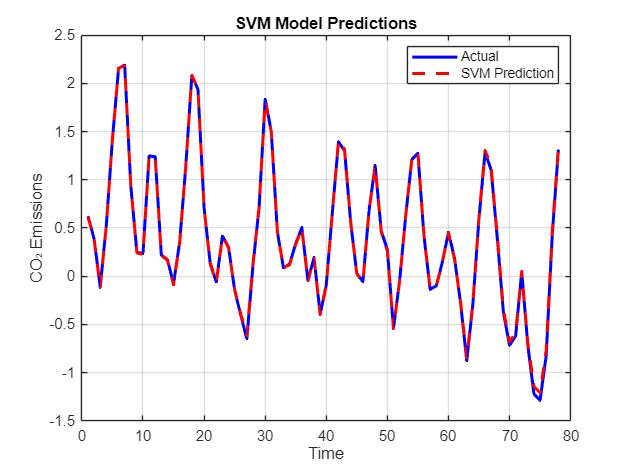


figure;
plot( YTest, 'b', 'LineWidth', 2); hold on;
plot(YPredSVM, 'r--', 'LineWidth', 2);
xlabel('Time');
ylabel('CO₂ Emissions');
legend('Actual', 'SVM Prediction');
title('SVM Model Predictions');
grid on;

**Explanation:**

- Performance metrics are calculated to evaluate the SVM model:

- `RMSE` (Root Mean Squared Error): Measures the average magnitude of the errors.

- `MAE` (Mean Absolute Error): Measures the average absolute errors.

- `MSE` (Mean Squared Error): Measures the average squared errors.

- `R²` (R-squared): Measures the proportion of the variance in the dependent variable that is predictable from the independent variables.

- The performance metrics are displayed to provide insights into the model's accuracy and reliability.

## Conclusion

The project demonstrates the application of various machine learning models to predict CO₂ emissions. Each model has its strengths and weaknesses, and the performance metrics provide insights into their accuracy and reliability. The LSTM model shows promising results for time-series forecasting, while XGBoost and LightGBM offer high accuracy with efficient computation. Linear Regression and SVM provide baseline comparisons.